# 1D Example

This example shows the behavior of regularizeNd in 1D. 

clc; clear; close all;

## Define Some Test Points

The dataset comes from  [https://mathformeremortals.wordpress.com/2013/01/29/introduction-to-regularizing-with-2d-data-part-1-of-3/](https://mathformeremortals.wordpress.com/2013/01/29/introduction-to-regularizing-with-2d-data-part-1-of-3/)

x = [0;0.55;1.1;2.6;2.99];
y = [1;1.1;1.5;2.5;1.9];

## setup 2 different grids. One course. One fine.

xGrid1 = {[-0.50,0,0.50,1,1.50,2,2.50,3,3.30,3.60]};
xGrid2 = {-0.5:0.1:3.6};

## Regularize

Try other smoothness values to see how they affect the fit. Change the values by a factor of 10 or more.

smoothness = 5e-3;
% smoothness = 1e-9;
% smoothness = 1e-1;

% smoothness = 1e-10; the problem is ill-conditioned for this value and the
% output is garbage.

yGrid1 = regularizeNd(x, y, xGrid1, smoothness);
% Alternative equivalent calls to regularizeNd
% yGrid1 = regularizeNd(x, y, xGrid1, smoothness, 'linear');
% yGrid1 = regularizeNd(x, y, xGrid1, smoothness, 'linear', 'normal');

yGrid2 = regularizeNd(x, y, xGrid2, smoothness);

## Plot the Regularized Lookup Table and Test Data

plot test data

% screenSize = get(0,'screensize');
% figure('position', [screenSize(3:4)*0.2, screenSize(3:4)*0.6])
plot(x,y,'rx', 'MarkerSize', 20, 'DisplayName', 'Test Points')
xlabel('x')
ylabel('y')
grid on;
hold all;

plot the lookup table

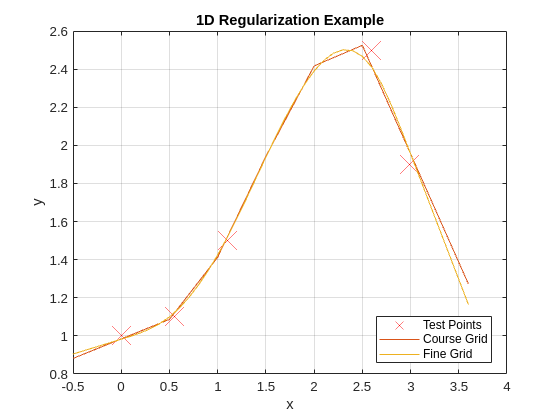

plot(xGrid1{1}, yGrid1, 'DisplayName', 'Course Grid')
plot(xGrid2{1}, yGrid2, 'DisplayName', 'Fine Grid')
legend('show', 'location', 'best')
title('1D Regularization Example')